clear all
clc

% HW02 - velocity control problem 
% Student Name: Giuditta Sigona
% Created on 18/04/2022
% Last version xx/yy/zz


% matlab colors
NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

s = tf('s');
om = logspace(-2,5,1000);
t = 0:0.001:10;


% parameters variations
J = ureal('J',0.02,'Percentage',[-50, 50]);
b = ureal('b',0.2,'Percentage',[-50, 50]);
K = ureal('K',0.1,'Percentage',[-20, 20]);
R = ureal('R',2,'PlusMinus',[-1.0, 1.0]);
L = ureal('L',0.5,'Percentage',[-50, 50]);

P1 = tf(K,[L R]);            % armature
P2 = tf(1,[J b]);            % eqn of motion          
sys = series(P1,P2)

sys =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 2 states.
  The model uncertainty consists of the following blocks:
    J: Uncertain real, nominal = 0.02, variability = [-50,50]%, 1 occurrences
    K: Uncertain real, nominal = 0.1, variability = [-20,20]%, 1 occurrences
    L: Uncertain real, nominal = 0.5, variability = [-50,50]%, 1 occurrences
    R: Uncertain real, nominal = 2, variability = [-1,1], 1 occurrences
    b: Uncertain real, nominal = 0.2, variability = [-50,50]%, 1 occurrences

Type "sys.NominalValue" to see the nominal value, "get(sys)" to see all properties, and "sys.Uncertainty" to interact with the uncertain elements.



Plant = feedback(sys, K);   % close back emf loop
tf(Plant)

ans =
 
        10
  ---------------
  s^2 + 14 s + 41
 
Continuous-time transfer function.



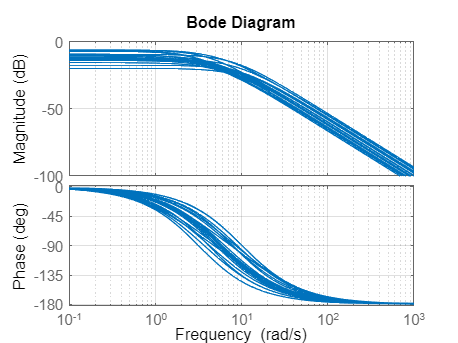

P_nom = Plant.nominal;


%figure(1)
bode(Plant), grid

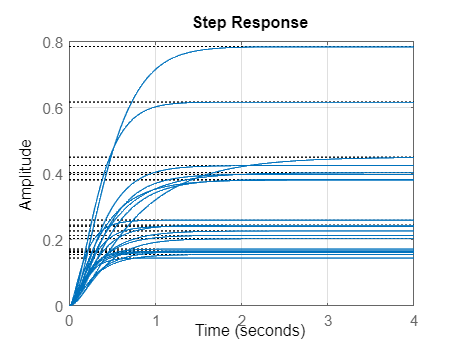

%figure(2)
step(Plant), grid

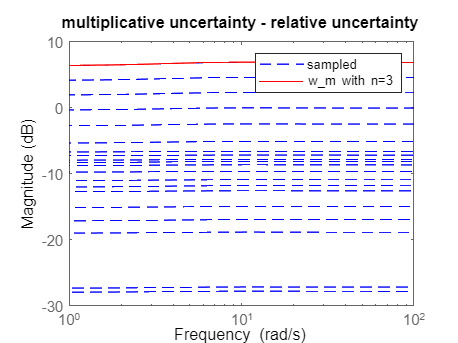


% how many samples of the system we want to work with
P_unc_sampled = gridureal(Plant,20);

%To find the corresponding weight, we can use the ucover command
%[usys,info] = ucover(Parray,Pnom,ord)

[PwM,InfoM] = ucover(P_unc_sampled,P_nom,3);
Rel_P = (P_nom-P_unc_sampled)/P_nom;
% figure(3)
% subplot(211)
bodemag(Rel_P,'b--',InfoM.W1,'r');
title('multiplicative uncertainty - relative uncertainty')
Leg = legend('sampled','w_m with n=3');


% controller for which the nominal closed loop system is type 1 and asymptotically stable
% C1 = 0.5/s

ContH_num = (1.792*10^4*s^2 + 2.508*10^5*s + 7.346*10^5);
ContH_den = (s^3 + 610.5*s^2 + 4.367*10^4*s + 1222);
C1 = ContH_num/ContH_den

C1 =
 
   17920 s^2 + 250800 s + 734600
  --------------------------------
  s^3 + 610.5 s^2 + 43670 s + 1222
 
Continuous-time transfer function.




% C1 = pidtune(sys, 'PID')
L1_unc  = C1*Plant;
CL1_unc = feedback(L1_unc,1);       % closed loop uncertain system
disp('closed loop poles: nominal case')

closed loop poles: nominal case


pole(CL1_unc.nominal)               % stability (as a check)

ans =  -528.5188
  -77.5807
   -9.8346
   -4.3341
   -4.2319



%we can see if the uncertain closed loop system is asymptotically stable or not using the command robstab
[stabmarg,wcu] = robstab(CL1_unc)

stabmarg = struct with fields:
           LowerBound: 1.4813
           UpperBound: 1.4989
    CriticalFrequency: 3.7140


wcu = struct with fields:
    J: 0.0350
    K: 0.0700
    L: 0.8747
    R: 0.5011
    b: 0.0501


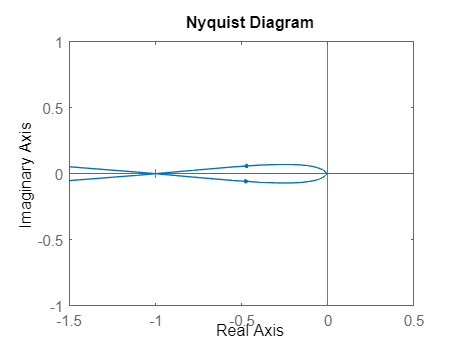


L_limit = C1*usubs(Plant,'J',wcu.J,'b',wcu.b,'K',wcu.K,'L',wcu.L,'R',wcu.R);
nyquist(L_limit), axis([-1.5,0.5,-1,1])

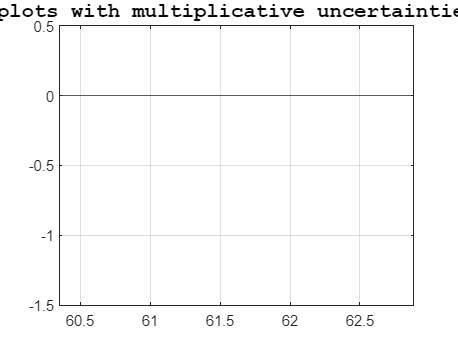



n = 50;
om = logspace(-0.5,1,n);
alpha = 0:0.01:2*pi;
%figure(3)
L1_n = L1_unc.Nom;
[ReL1n,ImL1n]=nyquist(L1_n);
plot(ReL1n(:),ImL1n(:),'-r','LineWidth',3), hold on
for i=1:n
    [ReL1w,ImL1w]=nyquist(L1_n,om(i));
    [radius,radiusp]=bode(L1_n*InfoM.W1,om(i));
    plot(ReL1w + radius*cos(alpha),ImL1w + radius*sin(alpha),'--b','LineWidth',1)
end
axis([-1.5,0.5,-1.5,0.5])
axis equal
grid
Tit=title('Nyquist plots with multiplicative uncertainties circles');
set(Tit,'FontName','Courier','FontSize',14);
xline(0);
yline(0);
hold off